# DESIGNING A ROBOT

This is a three fold problem:

- Motion planning

- Control: Velocities, accelerations, and forces

- Kinematics and dynamics + actuation and feedback.

## Motion Planning

clear; clc;
% We will use a mobile robot as a sample use case here:

% The first step is to find the work envelope, and determine the boundaries
% that exist in joint space and coordinate space.
% This can be found:
    % Using sensors such as the LIDAR to create a binary occupancy map
    % Knowing joint limits and establishing the work envelope
% For the mobile robot here we will load the maps file we have on src
load maps.mat
whos *Map*

  Name              Size               Bytes  Class      Attributes

  complexMap       41x52                2132  logical              
  emptyMap         26x27                 702  logical              
  simpleMap        26x27                 702  logical              
  ternaryMap      501x501            2008008  double               



% Convert the map to an occupancy grid. The map is in the form of a matrix
% that contains 1s and zeros, so we need to convert it to a grid.
map = binaryOccupancyMap(complexMap,2) % Resolution of 2 cells per meter

map =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 2
               GridSize: [41 52]
           XLocalLimits: [0 26]
           YLocalLimits: [0 20.5000]
           XWorldLimits: [0 26]
           YWorldLimits: [0 20.5000]


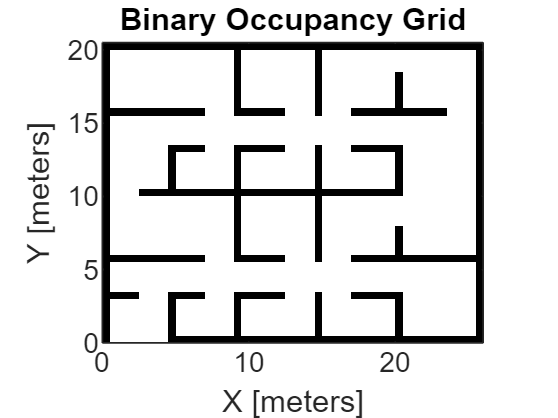

show(map)

% To avoid obstacles, define the robot as a circle with radius 0f 20cm.
robotRadius = 0.2; % Dimension given in meters
% To give a clearance, inflate the map by this radius then plan the path
% with that.
inflatedMap = copy(map);
inflate(inflatedMap,robotRadius);

% Display the inflated map
show(map)

### Path planning

% USe PRM (probabilistic model) to plan the path
prm = mobileRobotPRM;
prm.Map = inflatedMap; 

% The number of nodes is determined optimistically, higher number gives
% higher chances of getting a solution while it compromises the computation
% power.
prm.NumNodes = 1000;
% The connection distance is the maximum allowable distance between two
% nodes in a map. All nodes separated by thge distance below will be
% connected, to attempt to find a path. A large distance ensures a path can
% be found but increases computation power, a smaller distance is easier on
% the computation resources.
prm.ConnectionDistance = 100;


## Find path

startLocation = [3 0];
endLocation = [18 12];
path = findpath(prm, startLocation, endLocation)

path =     3.0000         0
    2.9194    0.1773
    3.3839    3.6690
    4.9159    4.5359
   15.6857    4.9597
   16.0704    5.9054
   17.3297    7.7017
   21.7839    9.6022
   21.4840   13.9448
   20.0774   14.1801


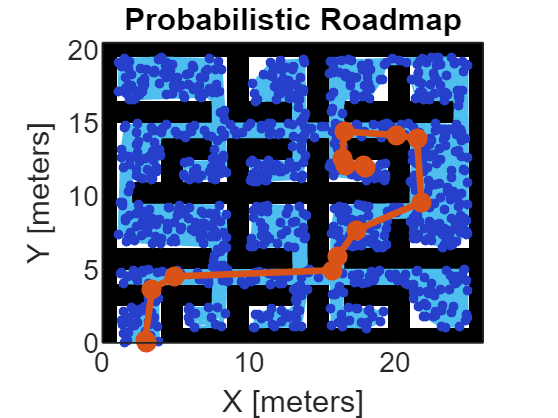

show(prm)

%% Instead of guessing the optimum path, we can tune it in real time by increasing it until we get a solution*
while isempty(path)
    % No feasible path found yet, increase the number of nodes
    prm.NumNodes = prm.NumNodes + 10;

    update(prm);
    
    % Search for a feasible path with the updated PRM
    path = findpath(prm, startLocation, endLocation);
end


## TRAJECTORY PLANNING

% This is now a trajectory planning problem, since we need time
sampleTime = 0.05; % We will track time every 0.05 seconds
tVec = 0:sampleTime:20; % Monitoring over a period of 20 seconds
initPose = [path(1,:)'; 0]; % Initial position - [x,y,theta]. This we would get from the robot itself
goalPose = [path(end, :)'; pi];

% Use a pure pursuit controller to give us the vehicle speed and angular
% speed
controller = controllerPurePursuit(Waypoints=path, DesiredLinearVelocity=3, MaxAngularVelocity=3*pi);
controller.LookaheadDistance = 0.5; % How much to cut corners

## ROBOT!!

% Create the differential drive robot model
robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");
distanceToGoal = norm(path(1,:) - path(end,:));



## Simulate and test the loop

sampleTime = 0.1;
visualizationRate = rateControl(1/sampleTime)

visualizationRate =   rateControl with properties:

         DesiredRate: 10
       DesiredPeriod: 0.1000
       OverrunAction: 'slip'
    TotalElapsedTime: 0.0348
          LastPeriod: NaN


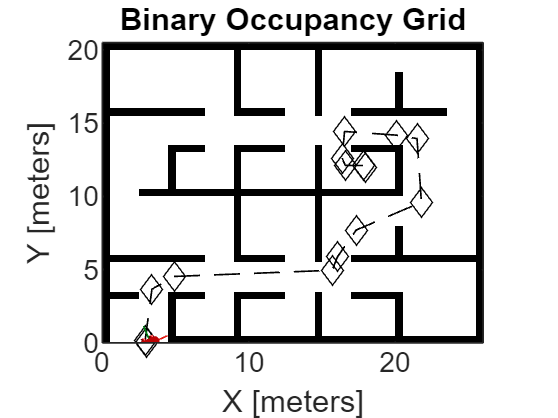

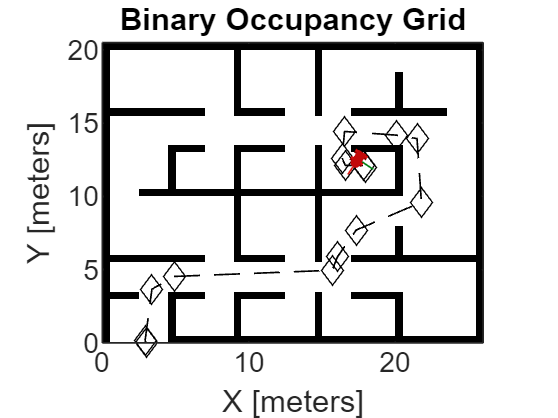


figure;
frameSize = robot.TrackWidth/0.8;

while( distanceToGoal > 0.5 )
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(initPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, initPose, [v omega]);
    
    % Update the current pose
    initPose = initPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(initPose(1:2) - path(end,:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    show(map);
    hold all
    plot(path(:,1), path(:,2),"k--d")
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [initPose(1:2); 0];
    plotRot = axang2quat([0 0 1 initPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0.0 26])
    ylim([0.0 20.5])
    
    waitfor(visualizationRate);
end